# RTES - Hossein Anjidani - HW02 - 400100746

## Q1)

### A)

idealcoefs = [1 -0.3 0.7 0.5 -0.8 1 1.2];
fixedpointcoefs = fi(idealcoefs, true, 11, 8);
disp(fixedpointcoefs)

    1.0000   -0.3008    0.6992    0.5000   -0.8008    1.0000    1.1992

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 11
        FractionLength: 8


syms z
idealFunc = load_coefs_to_syms(idealcoefs)

$$idealFunc = \frac{7}{10\,z^{2}}-\frac{3}{10\,z}+\frac{1}{2\,z^{3}}-\frac{4}{5\,z^{4}}+\frac{1}{z^{5}}+\frac{6}{5\,z^{6}}+1$$

FPFunc = load_coefs_to_syms(fixedpointcoefs.data)

$$FPFunc = \frac{179}{256\,z^{2}}-\frac{77}{256\,z}+\frac{1}{2\,z^{3}}-\frac{205}{256\,z^{4}}+\frac{1}{z^{5}}+\frac{307}{256\,z^{6}}+1$$

FPFunc_impulseResponse = iztrans(FPFunc, z)

$$FPFunc\_impulseResponse = \frac{179\,\delta_{z-2,0}}{256}-\frac{77\,\delta_{z-1,0}}{256}+\frac{\delta_{z-3,0}}{2}-\frac{205\,\delta_{z-4,0}}{256}+\delta_{z-5,0}+\frac{307\,\delta_{z-6,0}}{256}+\delta_{z,0}$$

### B)

errFunc = FPFunc-idealFunc

$$errFunc = -\frac{1}{1280\,z}-\frac{1}{1280\,z^{2}}-\frac{1}{1280\,z^{4}}-\frac{1}{1280\,z^{6}}$$

errFunc_impulseResponse = iztrans(errFunc, z)

$$errFunc\_impulseResponse = -\frac{\delta_{z-1,0}}{1280}-\frac{\delta_{z-2,0}}{1280}-\frac{\delta_{z-4,0}}{1280}-\frac{\delta_{z-6,0}}{1280}$$

### C)

idealFilter = dfilt.dffir(idealcoefs)

idealFilter =      FilterStructure: 'Direct-Form FIR'          
          Arithmetic: 'double'                   
           Numerator: [1 -0.3 0.7 0.5 -0.8 1 1.2]
    PersistentMemory: false                      
                                                 

### D)

FPFilter = dfilt.dffir(fixedpointcoefs);
FPFilter.arithmetic = 'fixed';
specifyall(FPFilter); 
FPFilter.CoeffWordLength=11; FPFilter.NumFracLength= 8;
FPFilter.Signed= true;
FPFilter.InputWordLength=11; FPFilter.InputFracLength= 8;
FPFilter.OutputWordLength=11; FPFilter.OutputFracLength=8;
FPFilter.ProductWordLength=2*11; FPFilter.ProductFracLength=2*8;
FPFilter.AccumWordLength=2*11; FPFilter.AccumFracLength=2*8;
FPFilter

FPFilter =      FilterStructure: 'Direct-Form FIR'                                      
          Arithmetic: 'fixed'                                                
           Numerator: [1 -0.30078125 0.69921875 0.5 -0.80078125 1 1.19921875]
    PersistentMemory: false                                                  
                                                                             
     CoeffWordLength: 11                
      CoeffAutoScale: false             
       NumFracLength: 8                 
              Signed: true              
                                        
     InputWordLength: 11                
     InputFracLength: 8                 
                                        
     FilterInternals: 'SpecifyPrecision'
                                        
    OutputWordLength: 11                
    OutputFracLength: 8                 
                                        
   ProductWordLength: 22                
   ProductFracLength: 16 

### E)

errFunc_impulseResponse

$$errFunc\_impulseResponse = -\frac{\delta_{z-1,0}}{1280}-\frac{\delta_{z-2,0}}{1280}-\frac{\delta_{z-4,0}}{1280}-\frac{\delta_{z-6,0}}{1280}$$

[idealFilt_imp, t] = impz(idealFilter);
[FPFilt_imp, t] = impz(FPFilter);
err_imp = FPFilt_imp - idealFilt_imp

err_imp = 1.0e-03 *

         0
   -0.7813
   -0.7812
         0
   -0.7812
         0
   -0.7812


### F)

idealSOS = norm(idealFilt_imp,2)

idealSOS = 2.2159

errSOS = norm(err_imp)

errSOS = 0.0016

idealSOS / errSOS

ans = 1.4181e+03

### G)

x1 = [12.32, 12.421, 13.98, 12.98, 13.2142, 15.78, 12.80, 12.27];
x2 = [11.2, 13.4, 15.8, 16.7, 13.2, 1.3, 5.6, 7.8]

x2 =    11.2000   13.4000   15.8000   16.7000   13.2000    1.3000    5.6000    7.8000


#### Q5.9:

wordLen = 14;fracLen = 9;
FPFilter = dfilt.dffir(fixedpointcoefs);
FPFilter.arithmetic = 'fixed';
specifyall(FPFilter); 
FPFilter.CoeffWordLength=wordLen; FPFilter.NumFracLength= fracLen;
FPFilter.Signed= true;
FPFilter.InputWordLength=wordLen; FPFilter.InputFracLength = fracLen;
FPFilter.OutputWordLength=wordLen; FPFilter.OutputFracLength = fracLen;
FPFilter.ProductWordLength=2 * wordLen; FPFilter.ProductFracLength= 2 * fracLen;
FPFilter.AccumWordLength=2 * wordLen; FPFilter.AccumFracLength=2 * fracLen;
Q591 = filter(FPFilter, x1)

Q591 =    12.3203    8.7168  -13.1406   -8.3789   15.4316   -1.7559    7.7871   12.5430

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 14
        FractionLength: 9

        RoundingMethod: Convergent
        OverflowAction: Wrap
           ProductMode: SpecifyPrecision
     ProductWordLength: 28
 ProductFractionLength: 18
               SumMode: SpecifyPrecision
         SumWordLength: 28
     SumFractionLength: 18
         CastBeforeSum: false

Q592 = filter(FPFilter, x2)

Q592 =    11.1992   10.0312  -12.3984   -5.7852  -14.8320  -15.1152    4.6133    0.6855

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 14
        FractionLength: 9

        RoundingMethod: Convergent
        OverflowAction: Wrap
           ProductMode: SpecifyPrecision
     ProductWordLength: 28
 ProductFractionLength: 18
               SumMode: SpecifyPrecision
         SumWordLength: 28
     SumFractionLength: 18
         CastBeforeSum: false

#### Q5.6:

wordLen = 11;fracLen = 6;
FPFilter = dfilt.dffir(fixedpointcoefs);
FPFilter.arithmetic = 'fixed';
specifyall(FPFilter); 
FPFilter.CoeffWordLength=wordLen; FPFilter.NumFracLength= fracLen;
FPFilter.Signed= true;
FPFilter.InputWordLength=wordLen; FPFilter.InputFracLength = fracLen;
FPFilter.OutputWordLength=wordLen; FPFilter.OutputFracLength = fracLen;
FPFilter.ProductWordLength=2 * wordLen; FPFilter.ProductFracLength= 2 * fracLen;
FPFilter.AccumWordLength=2 * wordLen; FPFilter.AccumFracLength=2 * fracLen;
Q561 = filter(FPFilter, x1)

Q561 =    12.3125    8.7656  -13.0469   -8.2812   15.5938   -1.6094    7.9844   12.7500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 11
        FractionLength: 6

        RoundingMethod: Convergent
        OverflowAction: Wrap
           ProductMode: SpecifyPrecision
     ProductWordLength: 22
 ProductFractionLength: 12
               SumMode: SpecifyPrecision
         SumWordLength: 22
     SumFractionLength: 12
         CastBeforeSum: false

Q562 = filter(FPFilter, x2)

Q562 =    11.2031   10.0781  -12.3125   -5.6719  -14.6562  -14.9688    4.7812    0.8438

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 11
        FractionLength: 6

        RoundingMethod: Convergent
        OverflowAction: Wrap
           ProductMode: SpecifyPrecision
     ProductWordLength: 22
 ProductFractionLength: 12
               SumMode: SpecifyPrecision
         SumWordLength: 22
     SumFractionLength: 12
         CastBeforeSum: false

#### Q5.2:

wordLen = 7;fracLen = 2;
FPFilter = dfilt.dffir(fixedpointcoefs);
FPFilter.arithmetic = 'fixed';
specifyall(FPFilter); 
FPFilter.CoeffWordLength=wordLen; FPFilter.NumFracLength= fracLen;
FPFilter.Signed= true;
FPFilter.InputWordLength=wordLen; FPFilter.InputFracLength = fracLen;
FPFilter.OutputWordLength=wordLen; FPFilter.OutputFracLength = fracLen;
FPFilter.ProductWordLength=2 * wordLen; FPFilter.ProductFracLength= 2 * fracLen;
FPFilter.AccumWordLength=2 * wordLen; FPFilter.AccumFracLength=2 * fracLen;
Q521 = filter(FPFilter, x1)

Q521 =    12.2500    9.5000  -12.0000   -7.0000  -14.5000         0   10.5000   15.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 7
        FractionLength: 2

        RoundingMethod: Convergent
        OverflowAction: Wrap
           ProductMode: SpecifyPrecision
     ProductWordLength: 14
 ProductFractionLength: 4
               SumMode: SpecifyPrecision
         SumWordLength: 14
     SumFractionLength: 4
         CastBeforeSum: false

Q522 = filter(FPFilter, x2)

Q522 =    11.2500   10.7500  -11.2500   -4.5000  -12.5000  -13.2500    6.7500    2.7500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 7
        FractionLength: 2

        RoundingMethod: Convergent
        OverflowAction: Wrap
           ProductMode: SpecifyPrecision
     ProductWordLength: 14
 ProductFractionLength: 4
               SumMode: SpecifyPrecision
         SumWordLength: 14
     SumFractionLength: 4
         CastBeforeSum: false

#### Ideal Filter

ideal1 = filter(idealFilter, x1)

ideal1 =    12.3200    8.7250   18.8777   23.6407   15.4607   30.2749   39.8269   44.5843


ideal2 = filter(idealFilter, x2)

ideal2 =    11.2000   10.0400   19.6200   26.9400   16.9900   17.4100   37.0000   32.1500


[~, argmin] = min([norm(Q591.data - ideal1, 2), norm(Q561.data - ideal1, 2), norm(Q521.data - ideal1, 2)])

argmin = 2

Due to previous block analisys the appropriate representation for x1 vector calculation is Q5.6

[~, argmin] = min([norm(Q592.data - ideal2, 2), norm(Q562.data - ideal2, 2), norm(Q522.data - ideal2, 2)])

argmin = 3

Due to previous block analisys the appropriate representation for x2 vector calculation is Q5.2

## Q2)

### A)

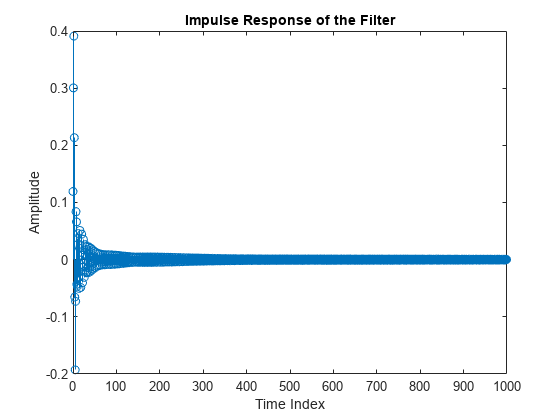

[sos, g] = ellip(8, 2, 30, 0.5); % Design an Elliptic filter
sosm = tf2sos(sos, g);
FI = dfilt.df2sos(sosm);
scale(FI, 'Linf', 'sosreorder', 'up');
FI.scalevalues;
FI.sosmatrix;
h = filter(FI, [1, zeros(1, 999)]);
x = 0:length(h)-1;
stem(x, h);
title('Impulse Response of the Filter');
xlabel('Time Index');
ylabel('Amplitude');

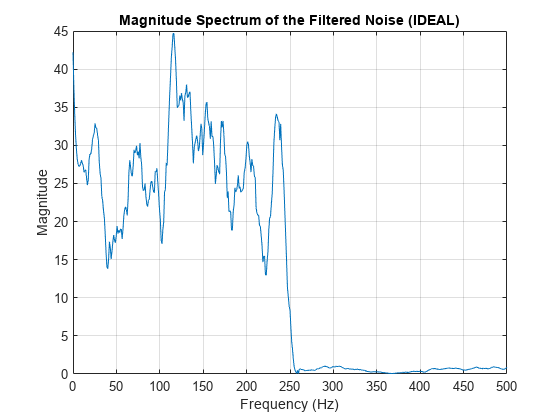

% Generate Gaussian noise with desired power
fs = 1000;
n = 1024; % Number of samples
desired_power = 1;

% Generate Gaussian noise
noise = randn(n, 1);

% Calculate the power of the generated noise
power_noise = var(noise);

% Scale the noise to achieve the desired power
scaling_factor = sqrt(desired_power / power_noise);
noise_scaled = noise * scaling_factor;

% Filter the noise
filtered_noise = filter(FI, noise_scaled);

% Compute the FFT of the filtered noise
N = length(filtered_noise);
fft_noise = fft(filtered_noise, N);
mag_fft_noise = abs(fft_noise);
f = fs * (0:(N/2)) / N;

% Smooth the magnitude spectrum
polyOrder = 3;
frameSize = 21;
smoothed_mag_fft = sgolayfilt(mag_fft_noise(1:N/2+1), polyOrder, frameSize);

% Plot the magnitude of the FFT
figure;
plot(f, smoothed_mag_fft);
title('Magnitude Spectrum of the Filtered Noise (IDEAL)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

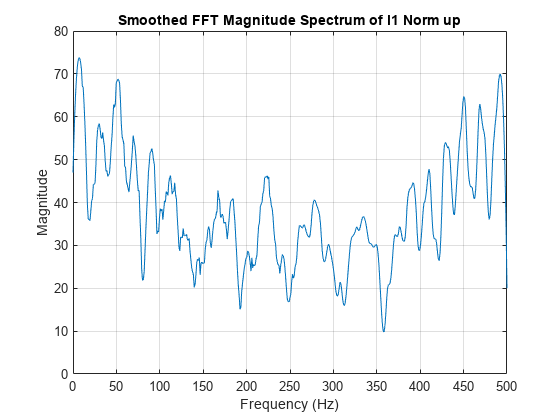

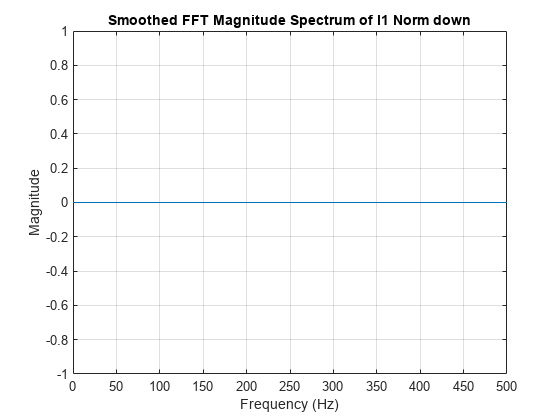

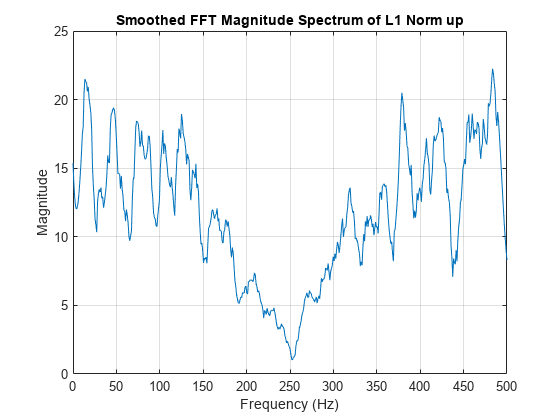

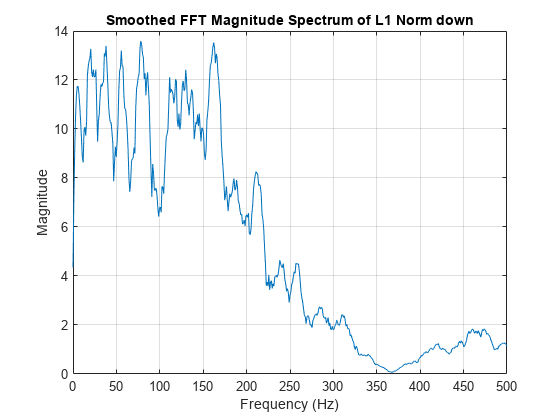

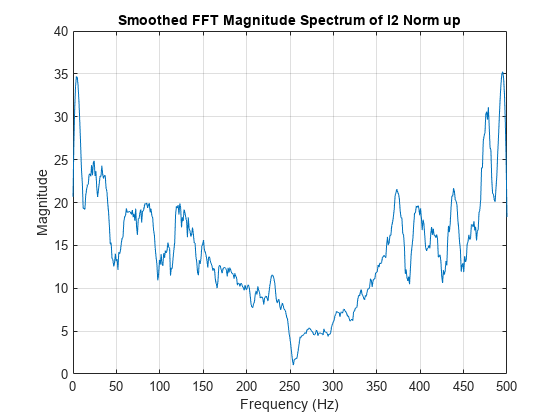

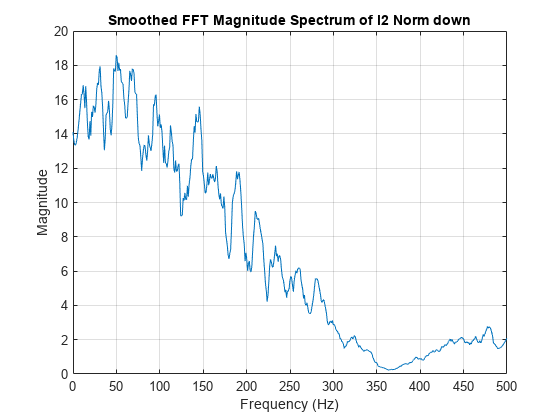

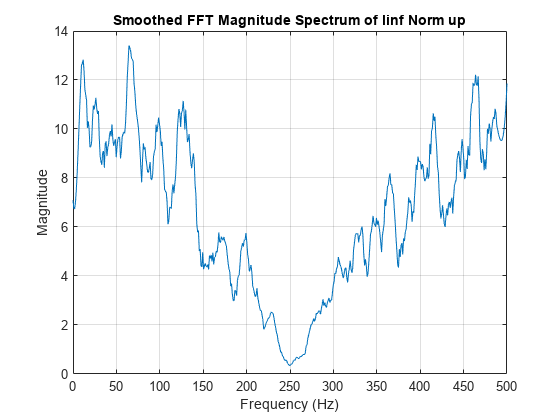

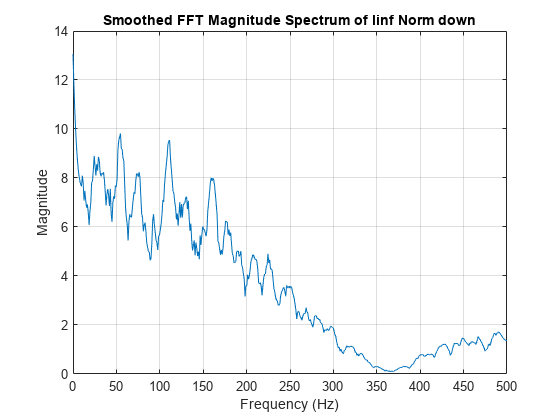


wordLength = 24;
fracLength = 16;
FI.arithmetic = 'fixed';
specifyall(FI);
FI.CoeffWordLength = wordLength;
FI.NumFracLength = fracLength;
FI.Signed = true;
FI.InputWordLength = wordLength;
FI.InputFracLength = fracLength;
FI.OutputWordLength = wordLength;
FI.OutputFracLength = fracLength;

norms = {'l1', 'L1', 'l2', 'linf', 'Linf'};
order = {'up', 'down'};

for norm_idx = 1:length(norms)
    for order_idx = 1:length(order)
        scale(FI, norms{norm_idx}, 'sosreorder', order{order_idx});
        filtered_signal = filter(FI, noise_scaled);
        smoothed_fft_filtered = computeAndSmoothFFT(filtered_signal, fs);
        plotFFT(f, smoothed_fft_filtered, [norms{norm_idx}, ' Norm ', order{order_idx}]);
    end
end

### 2)

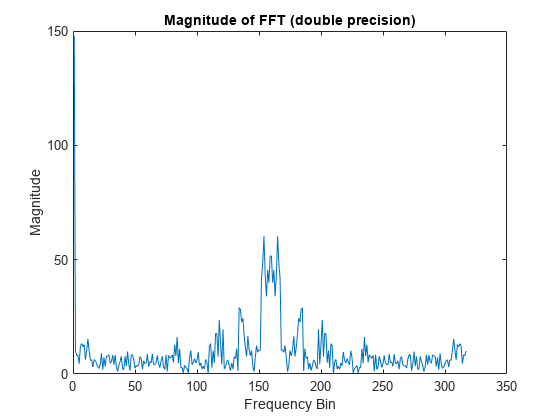

% Given impulse response
h = [-0.9, 0.8, -0.7, 0.5, -0.4, 0.3, -0.2, 0.1, 0, 1, -0.1, 0.2, -0.3, 0.4, -0.5, 0.7, -0.8, 0.9];
n = 300;
randSignal = rand(1,n);
% Convolve the random signal with the impulse response
y_double = conv(randSignal, h);

% Fixed-point conversion
numBits = 16; % Number of bits for fixed-point representation
fracBits = 15; % Number of fractional bits
h_fp = fi(h, 1, numBits, fracBits);
randNum_fp = fi(randSignal, 1, numBits, fracBits);
y_fp = conv(randNum_fp, h_fp);
N = length(y_fp);

% Compute the FFT
fft_double = fft(y_double, N);
fft_fp = fft(double(y_fp), N); % Converting fixed-point to double for FFT

% Plot the magnitude of the FFT results
figure;
plot(abs(fft_double));
title('Magnitude of FFT (double precision)');
xlabel('Frequency Bin');
ylabel('Magnitude');

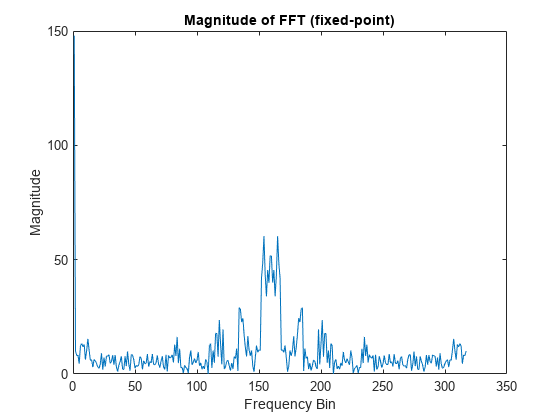


figure;
plot(abs(fft_fp));
title('Magnitude of FFT (fixed-point)');
xlabel('Frequency Bin');
ylabel('Magnitude');

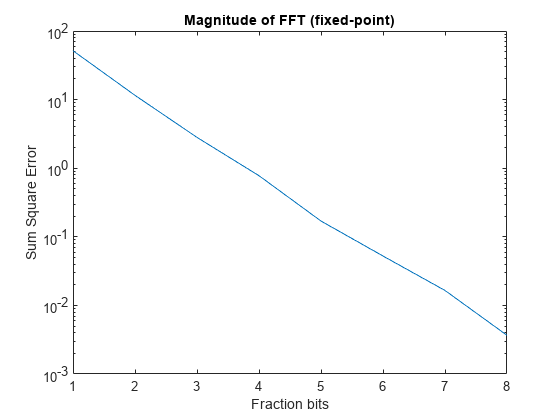

SSE = zeros(1, 8);
for fracBits = 1:8
    h_fp = fi(h, 1, fracBits + 8, fracBits);
    randNum_fp = fi(randSignal, 1, fracBits + 8, fracBits);
    y_fp = conv(randNum_fp, h_fp);
    SSE(fracBits) = sum((y_double - double(y_fp)).^2);
end
semilogy(SSE);
title('Magnitude of FFT (fixed-point)');
xlabel('Fraction bits');
ylabel('Sum Square Error');

As It is obvious in the plot; The more bit in fraction with fixed integer part; The more precise will the out put be in comparrison with double precision floating point.

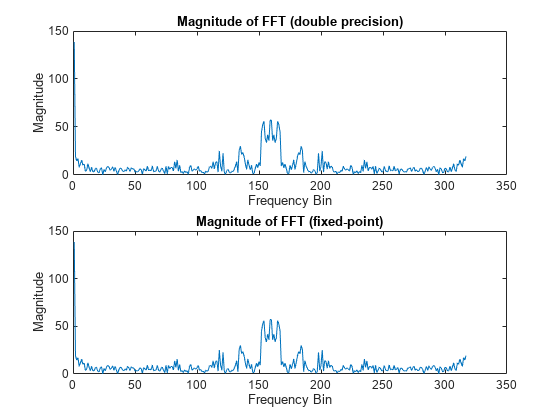

% FIR Filter
FI = dfilt.dffir(h);
specifyall(FI);
y_double_tb = filter(FI, randSignal);
FI.arithmetic = 'fixed';
specifyall(FI);
y_fp_tb = filter(FI, randSignal);
y_fp_converted_tb = double(y_fp_tb);

% Compute the FFT
fft_double_tb = fft(y_double_tb, N);
fft_fp_tb = fft(double(y_fp_converted_tb), N); % Converting fixed-point to double for FFT

% Plot the magnitude of the FFT results
figure;
subplot(2, 1, 1);
plot(abs(fft_double_tb));
title('Magnitude of FFT (double precision)');
xlabel('Frequency Bin');
ylabel('Magnitude');

subplot(2, 1, 2);
plot(abs(fft_fp_tb));
title('Magnitude of FFT (fixed-point)');
xlabel('Frequency Bin');
ylabel('Magnitude');

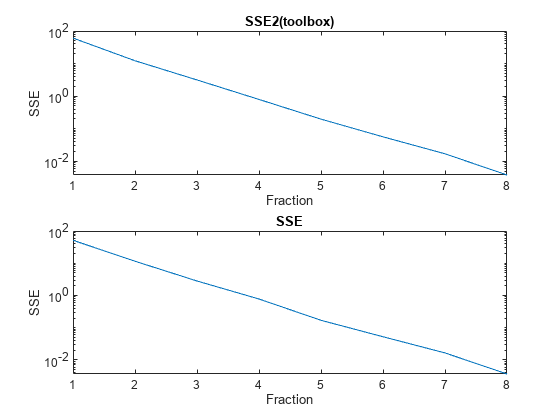

% SSE calculation using toolbox
SSE2 = zeros(1, 8);
for fracLength = 1:8
    worldLength = fracLength + 9;
    FI.arithmetic = 'fixed';
    specifyall(FI);
    FI.CoeffWordLength = worldLength;
    FI.NumFracLength = fracLength;
    FI.Signed = true;
    FI.InputWordLength = worldLength;
    FI.InputFracLength = fracLength;
    FI.OutputWordLength = worldLength;
    FI.OutputFracLength = fracLength;
    FI.ProductWordLength = 2 * worldLength;
    FI.ProductFracLength = 2 * fracLength;
    FI.AccumWordLength = 2 * worldLength;
    FI.AccumFracLength = 2 * fracLength;
    y_fp_tb = filter(FI, randSignal);
    y_fp_converted_tb = double(y_fp_tb);
    SSE2(fracLength) = sum((y_double_tb - y_fp_converted_tb).^2);
end

% Plot the SSE results
figure;
subplot(2, 1, 1);
semilogy(SSE2);
title('SSE2(toolbox)');
xlabel('Fraction');
ylabel('SSE');

subplot(2, 1, 2);
semilogy(SSE);
title('SSE');
xlabel('Fraction');
ylabel('SSE');

## Q3)

### A)

% Test parameters
angle = [pi/6 pi/2 pi/4 5*pi/6 2*pi];
n_iterations = 16;
word_length = 16;
frac_length = 12;

% Compute sine and cosine using CORDIC
[sin_val, cos_val] = cordic(10, angle)

sin_val =     0.4989    1.0000    0.7062    0.4989    0.0012


cos_val =     0.8666    0.0012    0.7080   -0.8666    1.0000



% Compare with MATLAB's built-in sin and cos functions
sin_ref = sin(angle);
cos_ref = cos(angle);

% Print the results
fprintf('Angle: %.4f radians\n', angle);

Angle: 0.5236 radians
Angle: 1.5708 radians
Angle: 0.7854 radians
Angle: 2.6180 radians
Angle: 6.2832 radians


fprintf('CORDIC sin: %.4f\n', double(sin_val));

CORDIC sin: 0.4989
CORDIC sin: 1.0000
CORDIC sin: 0.7062
CORDIC sin: 0.4989
CORDIC sin: 0.0012


fprintf('MATLAB sin: %.4f\n', sin_ref);

MATLAB sin: 0.5000
MATLAB sin: 1.0000
MATLAB sin: 0.7071
MATLAB sin: 0.5000
MATLAB sin: -0.0000


fprintf('CORDIC cos: %.4f\n', double(cos_val));

CORDIC cos: 0.8666
CORDIC cos: 0.0012
CORDIC cos: 0.7080
CORDIC cos: -0.8666
CORDIC cos: 1.0000


fprintf('MATLAB cos: %.4f\n', cos_ref);

MATLAB cos: 0.8660
MATLAB cos: 0.0000
MATLAB cos: 0.7071
MATLAB cos: -0.8660
MATLAB cos: 1.0000


### B)

#### Single VS Double precision:

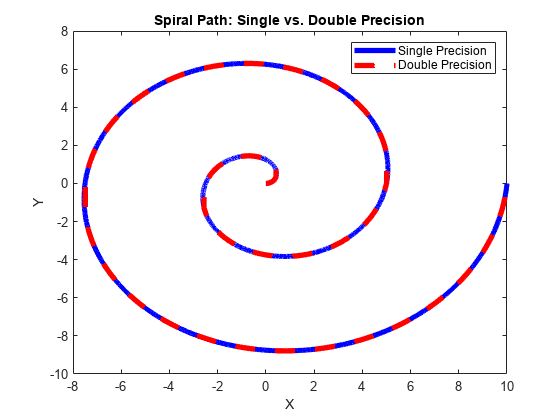

n=10000;
r = linspace(0, 10, n);
t = linspace(0, 4*pi, n);
x_single = sin(single(t)) .* r;
y_single = cos(single(t)) .* r;
x_double = sin(double(t)) .* r;
y_double = cos(double(t)) .* r;
figure;
plot(y_single, x_single, 'b-', y_double, x_double, 'r--', 'LineWidth', 4);
title('Spiral Path: Single vs. Double Precision');
xlabel('X');
ylabel('Y');
legend('Single Precision', 'Double Precision');

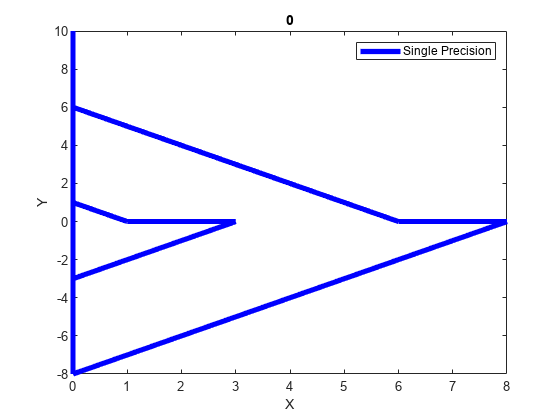

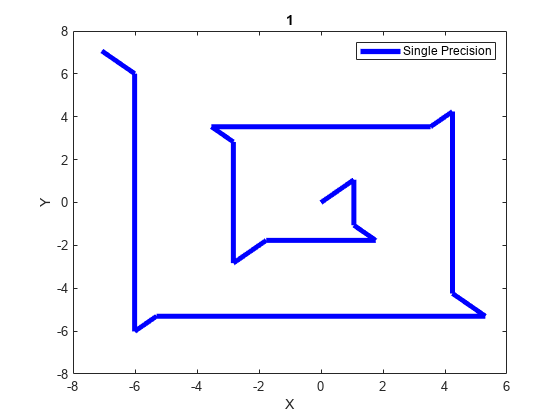

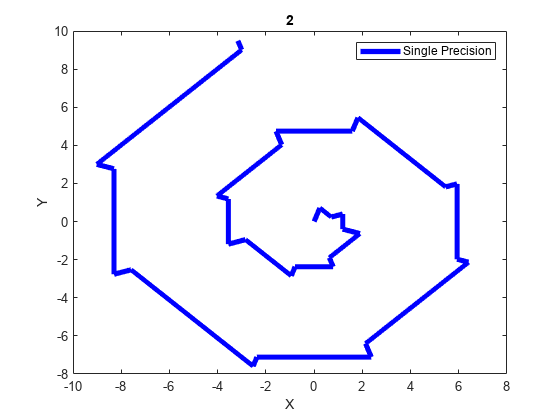

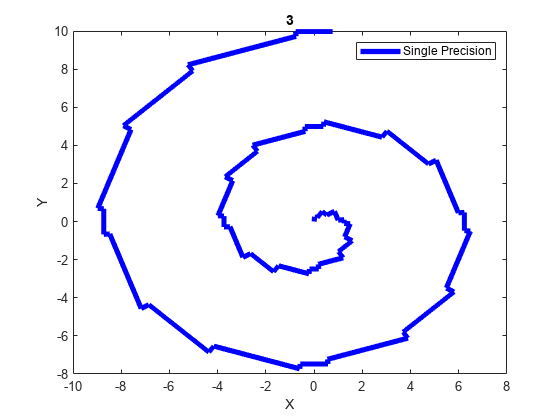

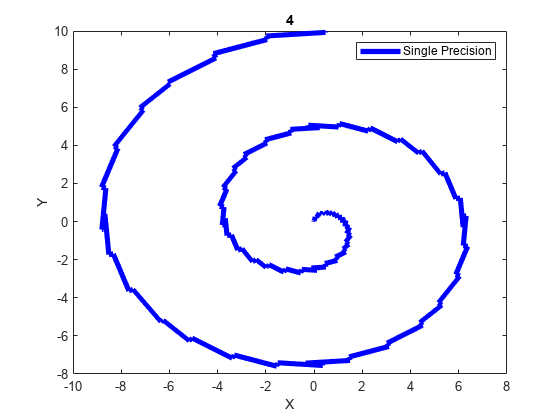

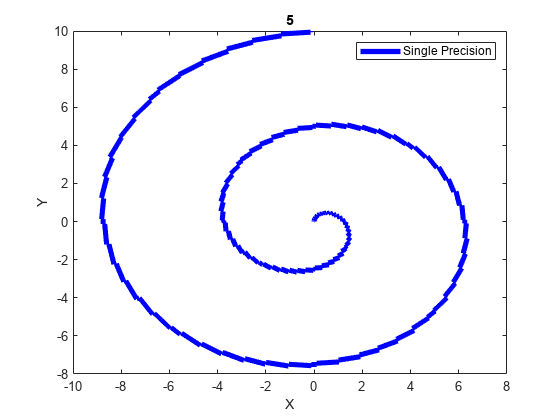

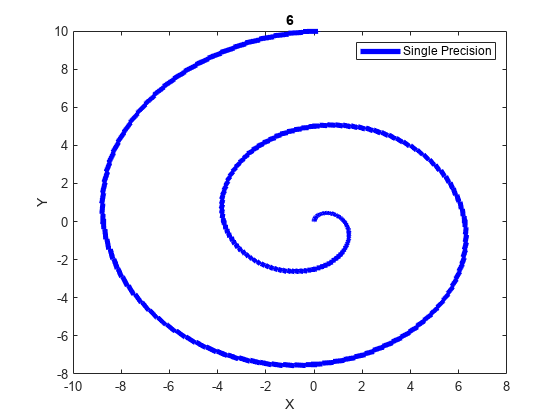

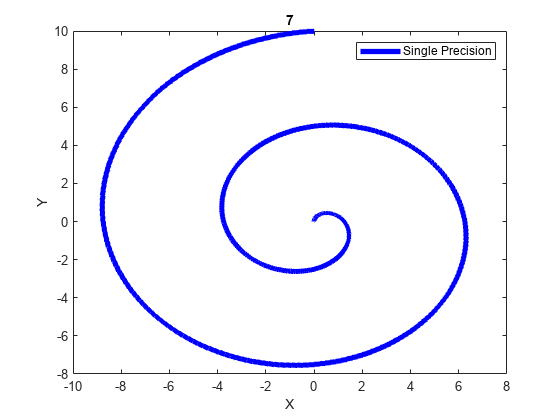

for frac = 0:16
    FPr = fi(r, 1, 5+frac, frac);
    Pt = fi(t,1,5+frac, frac);
    [y_single, x_single] = cordic(frac, Pt.data);
    y_single = FPr.data .* y_single;
    x_single = FPr.data .* x_single;
%     disp(x_single)
    figure;
    plot(y_single, x_single, 'b-','LineWidth', 4);
    title(num2str(frac));
    xlabel('X');
    ylabel('Y');
    legend('Single Precision');
end

### C)

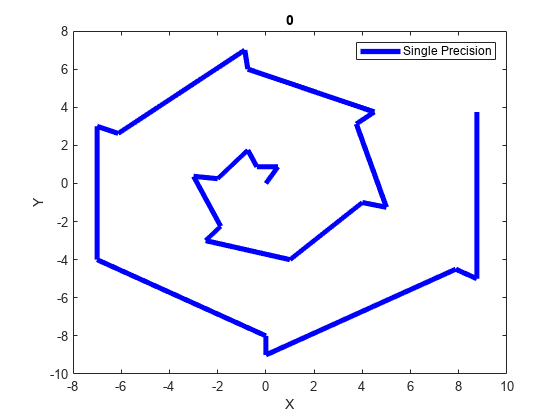

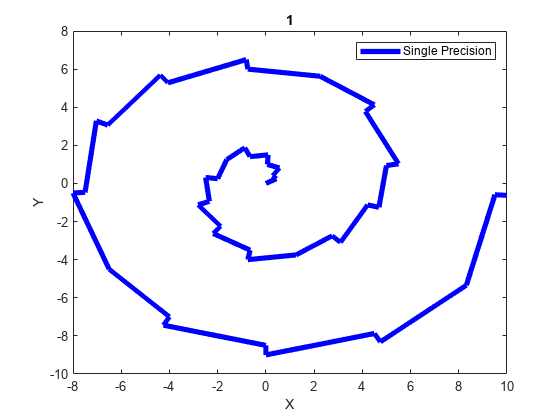

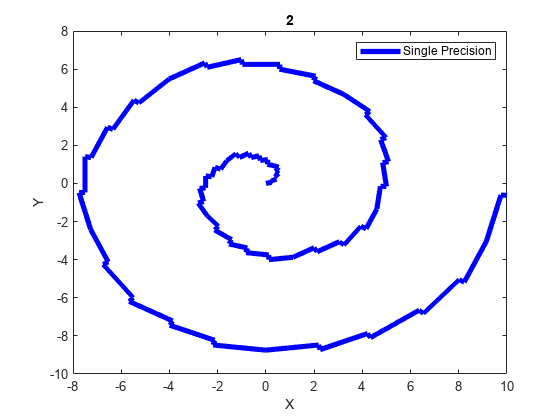

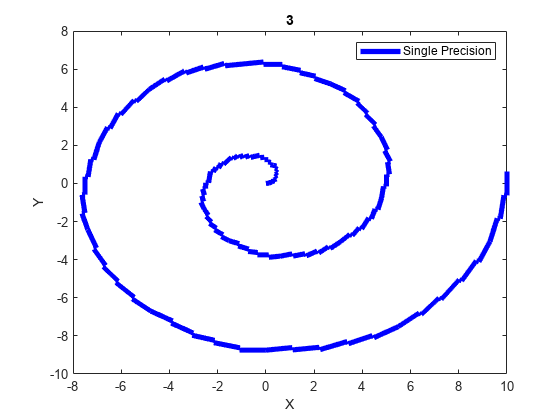

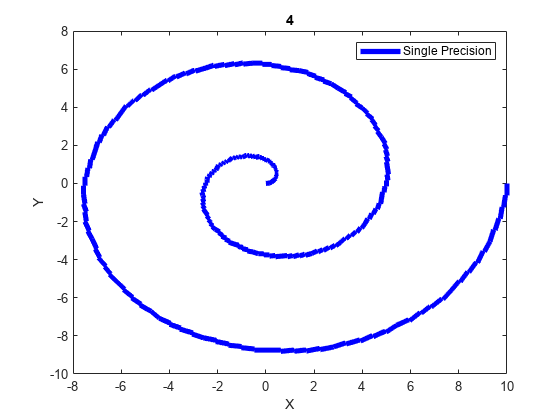

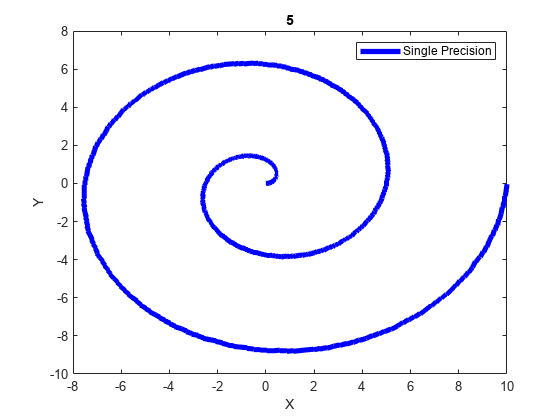

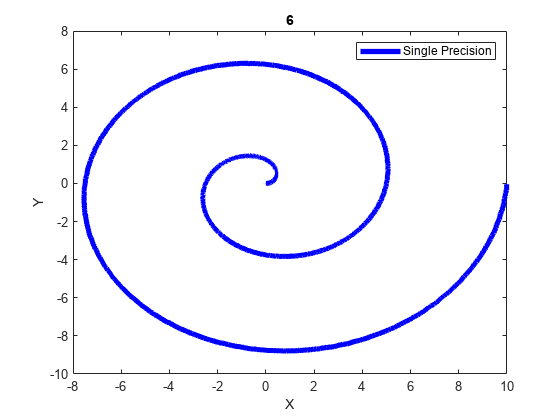

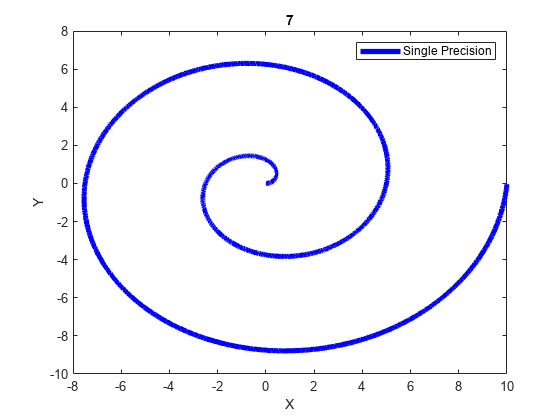

for frac = 0:16
    FPt = fi(t,1,5+frac, frac);
    FPr = fi(r,1,5+frac, frac);
    x_single = sin(single(FPt)) .* FPr;
    y_single = cos(single(FPt)) .* FPr;
    figure;
    plot(y_single, x_single, 'b-','LineWidth', 4);
    title(num2str(frac));
    xlabel('X');
    ylabel('Y');
    legend('Single Precision');
end

Because of the CORDIC calculation due to limited num of bits; The CORDIC function has kind of error in addition to fixed point entries.

function [sin_theta , cos_theta] = cordic(iterations , theta)
    cos_theta = zeros(size(theta));
    sin_theta = zeros(size(theta));
    % Constants
    K = 1/prod(sqrt(1 + 2.^(-2*(0:iterations-1))));
    % CORDIC angle table (in radians)
    angle_table = atan(2.^-(0:iterations-1));
    % Initialize x, y, and current angle
    x = ones(size(theta))*K;  % cos(0) scaled by K
    y = zeros(size(theta));  % sin(0)
    theta(theta>=2*pi) = mod(theta(theta>=2*pi),2*pi);
    con1 = theta < pi/2 & theta >=0;
    con2 = theta < pi & theta >=pi/2;
    con3 = theta < 1.5*pi & theta >=pi;
    con4 = ~(con1 | con2 | con3);
    z = theta;
    z(con2) = pi / 2 - theta(con2);
    z(con3) = pi - theta(con3);
    z(con4) = 2*pi - theta(con4);
    % CORDIC rotation loop
    for i = 1:iterations
        dx = x;
        dy = y;
%         dx
%         dy
        prz = z;
        x(prz<0) = dx(prz<0) + dy(prz<0) * 2^(-(i-1));
        x(prz>=0) = x(prz>=0) - dy(prz>=0) * 2^(-(i-1));
        y(prz<0) = dy(prz<0) - dx(prz<0) * 2^(-(i-1));
        y(prz>=0) = y(prz>=0) + dx(prz>=0) * 2^(-(i-1));
        z(prz<0) = z(prz<0) + angle_table(i);
        z(prz>=0) = z(prz>=0) - angle_table(i);
    end

    cos_theta(con1) = x(con1);
    sin_theta(con1) = y(con1);
    cos_theta(con2) = y(con2);
    sin_theta(con2) = x(con2);
    cos_theta(con3) = -x(con3);
    sin_theta(con3) = y(con3);
    cos_theta(con4) = x(con4);
    sin_theta(con4) = -y(con4);
end
function smoothed_fft = computeAndSmoothFFT(signal)
    signal = double(signal);
    N = length(signal);
    fft_signal = fft(signal, N);
    mag_fft_signal = abs(fft_signal);
    polyOrder = 3;
    frameSize = 21;
    if N > frameSize
        smoothed_fft = sgolayfilt(mag_fft_signal(1:N/2+1), polyOrder, frameSize);
    else
        smoothed_fft = mag_fft_signal(1:N/2+1);
    end
end

function plotFFT(frequencies, smoothed_fft, titleStr)
    figure;
    plot(frequencies, smoothed_fft);
    title(['Smoothed FFT Magnitude Spectrum of ', titleStr]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    grid on;
end


function [expr] = load_coefs_to_syms(coefs)
    % Define the number of coefficients
    n = length(coefs);
    
    % Create symbolic variables
    syms z
    syms c1 c2 c3 c4 c5 c6 c7
    
    % Create a cell array to hold the symbolic coefficients
    c = {c1, c2, c3, c4, c5, c6, c7};
    
    % Load the coefficients from the input array
    for i = 1:n
        c{i} = coefs(i);
    end
    
    % Create the symbolic expression
    expr = 0;
    for i = 1:n
        expr = expr + c{i} * z^(-(i-1));
    end
end